# MAE 204 FINAL PROJECT (DUE THURSDAY 3/24) AND COMP (3/24)

#### Written by Nandan Seshadri (A59018150)

## Input parameters

clear; close; clc; 

% Joint angles
Theta = [0, -(pi/2), pi/4, -(pi/2), -(pi/2), -(pi/4)]';

%Initialising inputs
dt = 0.01; % time step
Max_v = 2; % max joint velocity 
v_e = zeros(6,1);
theta_dot = zeros(6,1); % Joint velocities
error_twist = zeros(6,1);
prev_v_err = 0; % Previous errors

%PI gains
%Gains for best and new task
Kp = 2*eye(6);
Ki = 0*eye(6);

%Gains for overshoot
% Kp = 2*eye(6);
% Ki = 1*eye(6);

% Transformation matrices
M = [ 1 0 0 457; 0 1 0 78; 0 0 1 155; 0 0 0 1];

% best and overshoot case
Tse_i = [[0, 1, 0, 247]; [1, 0, 0, -169]; [0, 0, -1, 782]; [0, 0, 0, 1]];
Tce_g = [[0, 0, 1, 450]; [-1, 0, 0, -300]; [0, -1, 0, 65]; [0, 0, 0, 1]];
Tsc_i = [[0, 0, 1, 450]; [-1, 0, 0, -300]; [0, -1, 0, 0]; [0, 0, 0, 1]]; 
Tce_s = [[1, 0, 0, 0]; [0, 0, 1, 100]; [0, -1, 0, 65]; [0, 0, 0, 1]];
Tsc_f = [[1, 0, 0, 0]; [0, 0, 1, 100]; [0, -1, 0, 0]; [0, 0, 0, 1]];

% new task
% Tse_i = [[0, 1, 0, 247]; [1, 0, 0, -169]; [0, 0, -1, 782]; [0, 0, 0, 1]];
% Tce_g = [[0, 0, 1, 450]; [-1, 0, 0, -500]; [0, -1, 0, 65]; [0, 0, 0, 1]];
% Tsc_i = [[0, 0, 1, 450]; [-1, 0, 0, -500]; [0, -1, 0, 0]; [0, 0, 0, 1]];
% Tce_s = [[1, 0, 0, 0]; [0, 0, 1, 100]; [0, -1, 0, 65]; [0, 0, 0, 1]];
% Tsc_f = [[1, 0, 0, 0]; [0, 0, 1, 100]; [0, -1, 0, 0]; [0, 0, 0, 1]];

Slist = [[0 0 1 -300 0 0]',[0 1 0 -240 0 0]', [0 1 0 -240 0 244]', [0 1 0 -240 0 457]', [0 0 -1 169 457 0]', [0 1 0 -155 0 457]'];

## Wrapper code

Trajectory = TrajectoryGenerator(Tse_i,Tce_g,Tsc_i,Tsc_f, Tce_s,dt);

% Constructing trajectory matrices for csv
r11 = Trajectory(:,1);
r12 = Trajectory(:,2);
r13 = Trajectory(:,3);
r21 = Trajectory(:,4);
r22 = Trajectory(:,5);
r23 = Trajectory(:,6);
r31 = Trajectory(:,7);
r32 = Trajectory(:,8);
r33 = Trajectory(:,9);
px = Trajectory(:,10);
py = Trajectory(:,11);
pz = Trajectory(:,12);

for i = 1:(length(Trajectory)-1)    
    T_se = FKinSpace(M,Slist,Theta(:,i));
    Tse_d =  [r11(i), r12(i), r13(i), px(i); r21(i), r22(i), r23(i), py(i); r31(i), r32(i), r33(i), pz(i); 0, 0, 0, 1]; % desired transformation matrix
    Tse_dn =  [r11(i+1), r12(i+1), r13(i+1), px(i+1); r21(i+1), r22(i+1), r23(i+1), py(i+1); r31(i+1), r32(i+1), r33(i+1), pz(i+1); 0, 0, 0, 1]; % desired next transformation matrix
    [theta_dot(:,i), Je, error_twist(:,i), v_d, v_e(:,i)] = FeedbackControl(T_se,Tse_d,Tse_dn, Kp, Ki, dt, Slist, prev_v_err, Theta(:,i)); 
    joint_vel = [theta_dot(1,:); theta_dot(2,:); theta_dot(3,:); theta_dot(4,:); theta_dot(5,:); theta_dot(6,:)];
    Theta(:,i+1) = NextStateFunc(Theta(:,i),joint_vel(:,i),Max_v,dt);           
end

% Generating csv
fb_simulation = horzcat(Theta',Trajectory(:,13));
writematrix(Trajectory,'trajectoryOutput.csv'); 
writematrix(fb_simulation,'Angles.csv')

#### Plotting error twists

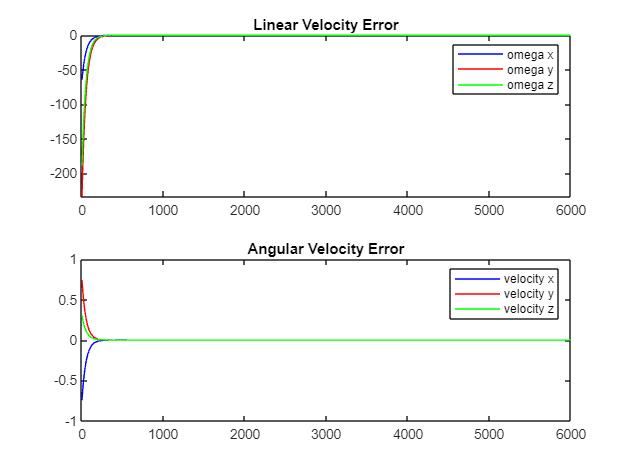

subplot(2,1,1);
plot(error_twist(4,:), 'b');
hold on;
plot(error_twist(5,:), 'r');  
plot(error_twist(6,:), 'g');  
title('Linear Velocity Error');
legend('omega x', 'omega y', 'omega z')
hold off;

subplot(2,1,2);
plot(error_twist(1,:), 'b');  % plot the first row in blue
hold on;
plot(error_twist(2,:), 'r');  % plot the second row in red
plot(error_twist(3,:), 'g');  % plot the third row in green
title('Angular Velocity Error');
legend('velocity x', 'velocity y', 'velocity z')
hold off;

## Functions

#### Trajectory generator

function Trajectory = TrajectoryGenerator(Tse_i,Tce_g,Tsc_i,Tsc_f, Tce_s, dt) % uncomment for project 

% function Trajectory = TrajectoryGenerator(Tse_i,Tce_g,Tsc_i,Tsc_f, Tce_s, dt, Slist, M, thetalist0)

t = 10;
N = t/dt;
m = 5; % (5 is quintic, 3 is cubic)

for i = 1:t 
    if i == 1 
        traj1 = CartesianTrajectory(Tse_i, Tce_g, t, N, m);
        traj1_mat = cell2mat(traj1');
        r1_traj1 = traj1_mat(1:4:end,1:3); 
        r2_traj1 = traj1_mat(2:4:end,1:3); 
        r3_traj1 = traj1_mat(3:4:end,1:3); 
        px_traj1 = traj1_mat(1:4:end,4); 
        py_traj1 = traj1_mat(2:4:end,4);
        pz_traj1 = traj1_mat(3:4:end,4);
        grip_1 = zeros(N,1); % gripper is open
        M1 = horzcat(r1_traj1,r2_traj1,r3_traj1,px_traj1,py_traj1,pz_traj1,grip_1); 
    end
    i = i+1;
    
    if i == 2
        traj2 = ScrewTrajectory(Tce_g, Tsc_i, t, N, m);
        traj2_mat = cell2mat(traj2');
        r1_traj2 = traj2_mat(1:4:end,1:3);
        r2_traj2 = traj2_mat(2:4:end,1:3);
        r3_traj2 = traj2_mat(3:4:end,1:3);
        px_traj2 = traj2_mat(1:4:end,4);
        py_traj2 = traj2_mat(2:4:end,4);
        pz_traj2 = traj2_mat(3:4:end,4);
        grip_2 = zeros(N,1);
        M2 = horzcat(r1_traj2,r2_traj2,r3_traj2,px_traj2,py_traj2,pz_traj2,grip_2);
    end
    i = i+1;
   
    if i == 3
        traj3 = ScrewTrajectory(Tsc_i, Tce_g, t, N, m);
        traj3_mat = cell2mat(traj3');
        r1_traj3 = traj3_mat(1:4:end,1:3);
        r2_traj3 = traj3_mat(2:4:end,1:3);
        r3_traj3 = traj3_mat(3:4:end,1:3);
        px_traj3 = traj3_mat(1:4:end,4);
        py_traj3 = traj3_mat(2:4:end,4);
        pz_traj3 = traj3_mat(3:4:end,4);
        grip_3 = ones(N,1); %gripper is closed
        M3 = horzcat(r1_traj3,r2_traj3,r3_traj3,px_traj3,py_traj3,pz_traj3,grip_3);
    end
    i = i+1;

    if i == 4
        traj4 = ScrewTrajectory(Tce_g, Tce_s, t, N, m);
        traj4_mat = cell2mat(traj4');
        r1_traj4 = traj4_mat(1:4:end,1:3);
        r2_traj4 = traj4_mat(2:4:end,1:3);
        r3_traj4 = traj4_mat(3:4:end,1:3);
        px_traj4 = traj4_mat(1:4:end,4);
        py_traj4 = traj4_mat(2:4:end,4);
        pz_traj4 = traj4_mat(3:4:end,4);
        grip_4 = ones(N,1);
        M4 = horzcat(r1_traj4,r2_traj4,r3_traj4,px_traj4,py_traj4,pz_traj4,grip_4);
    end
    i = i+1;
    
    if i == 5
        traj5 = ScrewTrajectory(Tce_s, Tsc_f, t, N, m);
        traj5_mat = cell2mat(traj5');
        r1_traj5 = traj5_mat(1:4:end,1:3);
        r2_traj5 = traj5_mat(2:4:end,1:3);
        r3_traj5 = traj5_mat(3:4:end,1:3);
        px_traj5 = traj5_mat(1:4:end,4);
        py_traj5 = traj5_mat(2:4:end,4);
        pz_traj5 = traj5_mat(3:4:end,4);
        grip_5 = ones(N,1);
        M5 = horzcat(r1_traj5,r2_traj5,r3_traj5,px_traj5,py_traj5,pz_traj5,grip_5);
    end
    i = i+1;
    
    if i == 6
        traj6 = ScrewTrajectory(Tsc_f, Tce_s, t, N, m);
        traj6_mat = cell2mat(traj6');
        r1_traj6 = traj6_mat(1:4:end,1:3);
        r2_traj6 = traj6_mat(2:4:end,1:3);
        r3_traj6 = traj6_mat(3:4:end,1:3);
        px_traj6 = traj6_mat(1:4:end,4);
        py_traj6 = traj6_mat(2:4:end,4);
        pz_traj6 = traj6_mat(3:4:end,4);
        grip_6 = zeros(N,1);
        M6 = horzcat(r1_traj6,r2_traj6,r3_traj6,px_traj6,py_traj6,pz_traj6,grip_6);
    end
    Trajectory = vertcat(M1,M2,M3,M4,M5,M6);   
end
end

#### Next state

function thetalist = NextStateFunc(thetalist,joint_vel,Max_vel,dt)
    if joint_vel >= Max_vel
        joint_vel = Max_vel;
    end
    thetalist = thetalist+(joint_vel*dt); % Eulers equation
end

#### Feedback control

function [theta_dot, Je, error_twist,v_d,v_e] = FeedbackControl(T_se, Tse_d, Tse_dn, Kp, Ki, delta_t, Slist, v_i, Theta)
    error_twist = se3ToVec(MatrixLog6(TransInv(T_se)*Tse_d)); 
    v_d = se3ToVec((1/delta_t)*MatrixLog6((TransInv(Tse_d)*Tse_dn)));
    v_adj = Adjoint(TransInv(T_se)*Tse_d); 
    v_i = v_i + delta_t*error_twist; 
    v_e = v_adj*v_d + Kp*error_twist + Ki*v_i;
    Je = Adjoint(TransInv(Tse_d))*JacobianSpace(Slist, Theta);
    theta_dot = pinv(Je)*v_e;
end